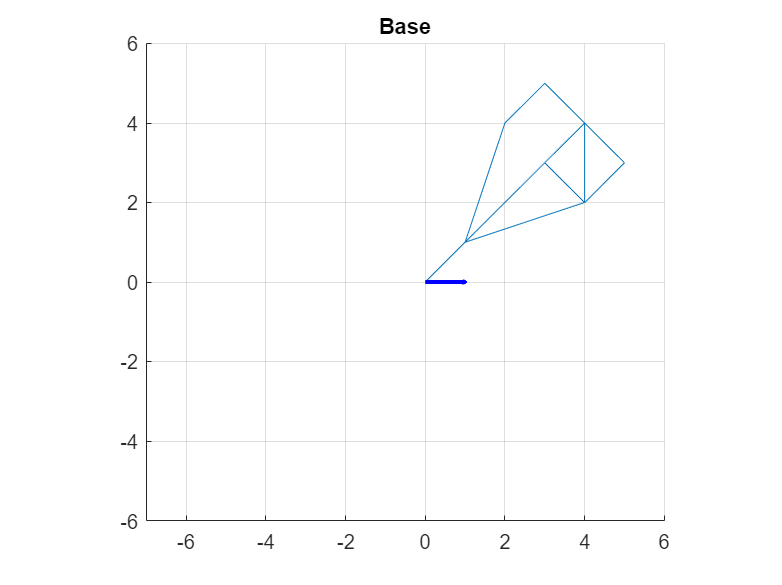

clf
clear
load('MT1A-G9-avbildningar.mat')
origo = [0; 0];
%drawArrow(origo, A)
hold on
grid on
axis equal
xlim([-7.0 6.0])
ylim([-6.0 6.0])

%X = [3, 2, 4, 4, 2, 4, 5, 2; 2, 3, 1, 5, 1, 3, 5, 3];

X = [0, 1, 2, 3, 4, 5, 4, 3, 4, 4, 1, 3;
     0, 1, 4, 5, 4, 3, 2, 3, 4, 2, 1, 3];
xLine = [1;
         0];

%X = randi(10, 2, 15)

plot(X(1,:), X(2, :))
drawArrow(origo, xLine, 'blue')
title('Base')

% spegel i V
clf
hold on
grid on
axis equal
xlim([-7.0 6.0])
ylim([-6.0 6.0])
V = eig(A)

V =     -1
     1


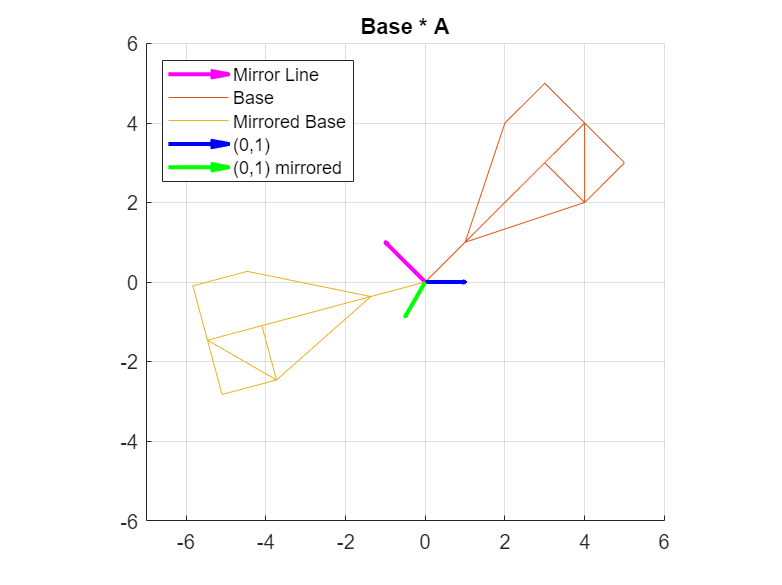

Ax = A*X;
AxLine = A*xLine;
drawArrow(origo, V, 'magenta')
plot(X(1,:), X(2, :))
plot(Ax(1,:), Ax(2, :))
drawArrow(origo, xLine, 'blue')
drawArrow(origo, AxLine, 'green')


%drawArrow(A(1,:), A(2,:))
legend('Mirror Line', 'Base', 'Mirrored Base', '(0,1)', '(0,1) mirrored', Location='northwest')
title('Base * A')

% rotationsmatris ca 150 grader
clf
hold on
grid on
axis equal
xlim([-7.0 6.0])
ylim([-6.0 6.0])

Bx = B*X;
BxLine = B*xLine;
plot(X(1,:), X(2, :))
plot(Bx(1,:), Bx(2, :))
drawArrow(origo, xLine, 'blue')
drawArrow(origo, BxLine, 'magenta')

title('Base * B')

sinDelta = norm(BxLine .* xLine)/(norm(BxLine)*norm(xLine))

sinDelta = 0.8660

asind(sinDelta) + 90

ans = 150.0000


cosVradians = dot(BxLine,xLine)/(norm(BxLine)*norm(xLine))

cosVradians = -0.8660

acosd(cosVradians)

ans = 150.0000

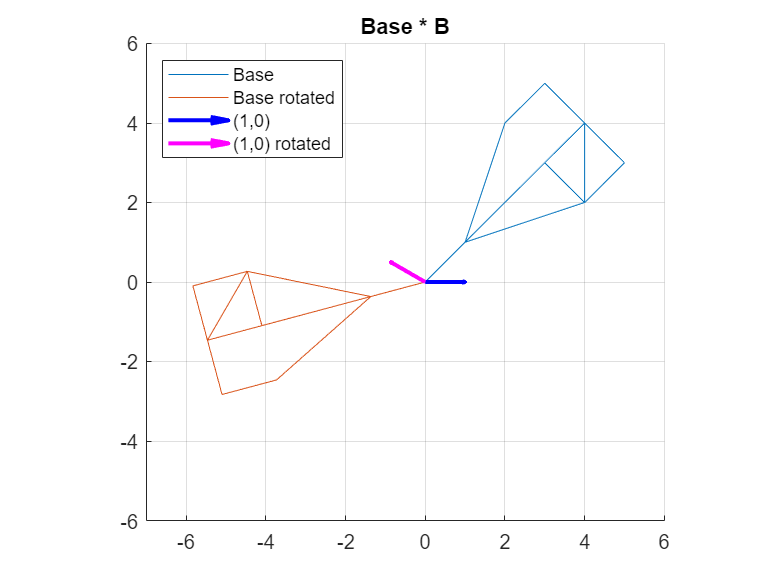

legend('Base', 'Base rotated', '(1,0)', '(1,0) rotated',Location='northwest')

% projektion på värderumet längs V(2,:)
clf
hold on
grid on
axis equal
xlim([-7.0 6.0])
ylim([-6.0 6.0])
[V,D] = eig(C)

V =     0.2588   -0.9659
   -0.9659   -0.2588


D =     0.0000         0
         0    1.0000


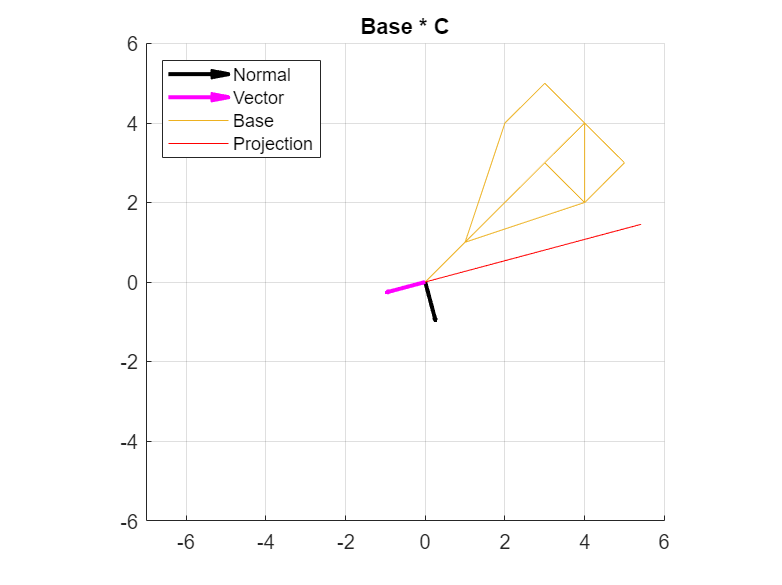

drawArrow(origo, V(1,:), 'black')
drawArrow(origo, V(2,:), 'magenta')
Cx = C*X;
CxLine = C*xLine;
plot(X(1,:), X(2, :))
%drawArrow(origo, CxLine)
plot(Cx(1,:), Cx(2, :), 'red')
%drawArrow(C(1,:), C(2,:))
legend('Normal', 'Vector', 'Base', 'Projection', Location='northwest')
title('Base * C')

% cube
% clf
% drawArrow(origo, A) % blue
% hold on
% grid on
% axis equal
% axis([-6 6 -6 6])
% drawArrow(origo, B)
% drawArrow(origo, C)
% drawArrow(A, B)
% drawArrow(A, C)
% drawArrow(B, C)
% drawArrow(B, B + C)
% drawArrow(C, B + C)
% drawArrow(A, A + C)
% drawArrow(C, A + C)
% drawArrow(A, A + B)
% drawArrow(B, A + B)

% 2 inverse of matrix
% clf
% hold on
% grid on
% axis equal
% axis([-6 6 -6 6])
% drawArrow(origo, A, 'blue')
% drawArrow(origo, -A, 'red')
% title('A and A inverse')
% clf
% hold on
% grid on
% axis equal
% drawArrow(origo, B, 'blue')
% drawArrow(origo, -B, 'red')
% title('B and B inverse')
% clf
% hold on
% grid on
% axis equal
% drawArrow(origo, C, 'blue')
% drawArrow(origo, -C, 'red')
% title('C and C inverse')
% %drawArrow(origo, invC)
% %drawArrow(origo, invA)

% like 3 eig?
% clf
% hold on
% grid on
% axis equal
% A1 = A(1,:)
% A2 = A(2,:)
% %det(A)
% eig(A)
% [valuesA, vectorsA] = eig(A)
% A
% drawArrow(origo, A(1,:), 'blue')
% drawArrow(origo, A(2,:), 'blue')
% drawArrow(origo, vectorsA(1,:), 'yellow')
% drawArrow(origo, vectorsA(2,:), 'yellow')
% drawArrow(origo, eig(A), 'yellow')
% 
% drawArrow(origo, vectorsA(1,:) * valuesA(1) * -1, 'red')
% drawArrow(origo, vectorsA(2,:) * valuesA(2) * -1, 'red')

% like 4 eig?
% clf
% hold on
% grid on
% axis equal
% drawArrow(origo, C(1,:), 'blue')
% drawArrow(origo, C(2,:), 'blue')
% [vectorsC, valuesC] = eig(C)
% drawArrow(origo, vectorsC(1,:), 'yellow')
% drawArrow(origo, vectorsC(1,:) * valuesC(1,1), 'black')
% drawArrow(origo, vectorsC(2,:), 'red')
% drawArrow(origo, vectorsC(2,:) * valuesC(2,2), 'cyan')

% like 5 AB
% clf
% hold on
% grid on
% axis equal
% A
% B
% newMatrix1 = B*A
% newMatrix2 = A*B
% drawArrow(origo, newMatrix1(1,:), 'blue')
% drawArrow(origo, newMatrix1(2,:), 'blue')
% drawArrow(origo, newMatrix2(1,:), 'green')
% drawArrow(origo, newMatrix2(2,:), 'green')
% drawArrow(origo, A(1,:), 'yellow')
% drawArrow(origo, A(2,:), 'yellow')
% drawArrow(origo, B(1,:), 'red')
% drawArrow(origo, B(2,:), 'red')